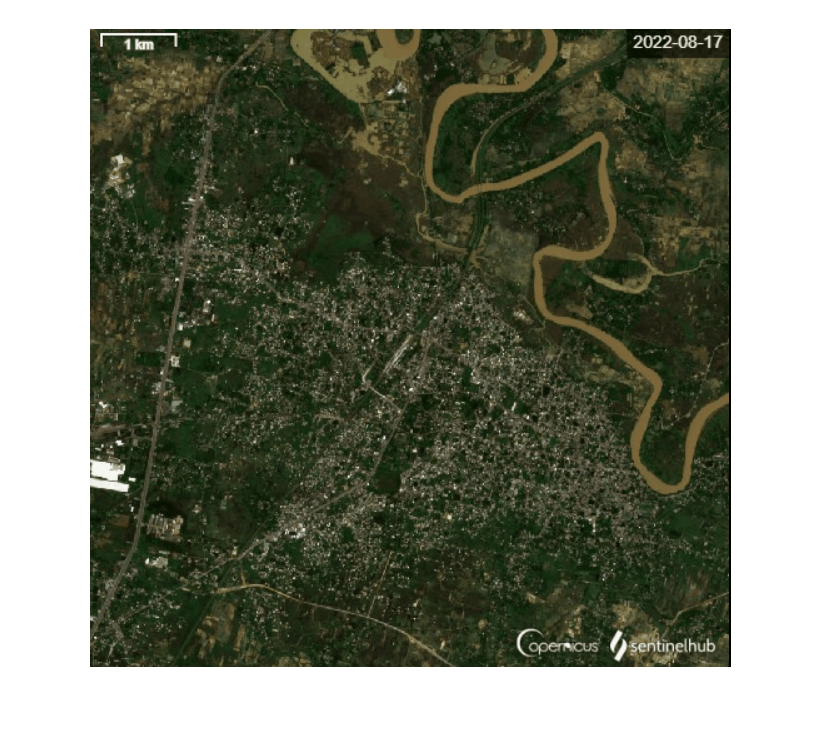

year1=imread('C:\Users\Sumit\OneDrive\Desktop\appi\image_appi\image1.png');
imshow(year1)

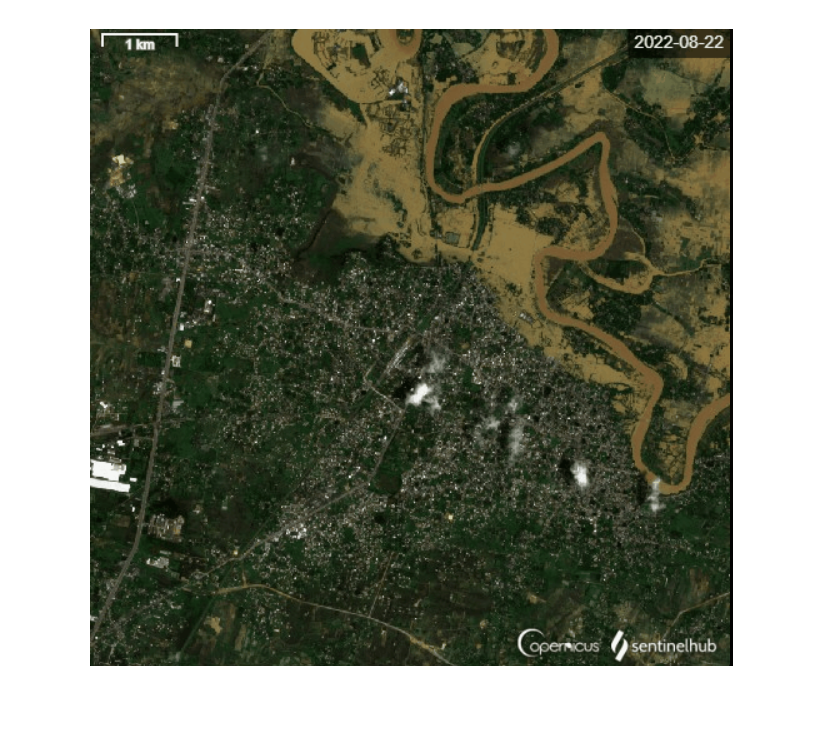

year2=imread('C:\Users\Sumit\OneDrive\Desktop\appi\image_appi\image2.png');
imshow(year2)

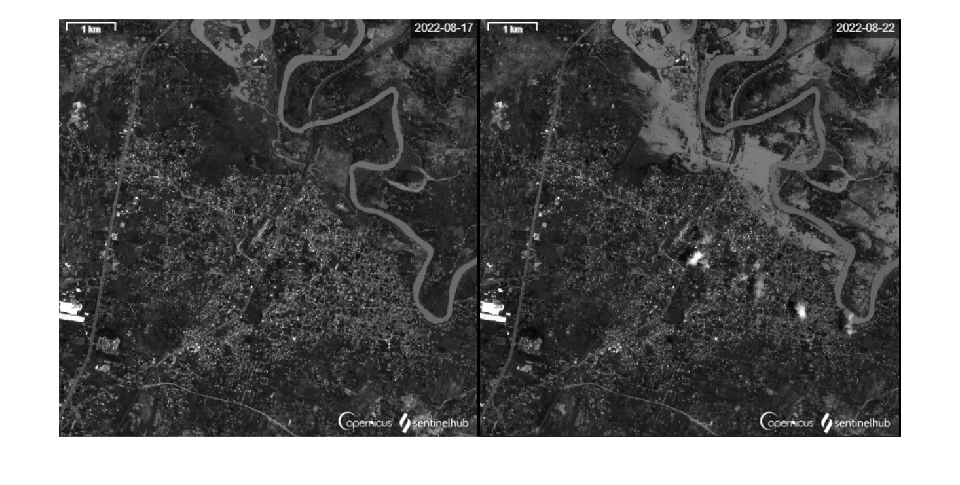

gy1=im2gray(year1);
gy2=im2gray(year2);
imshowpair(gy1,gy2,"montage");

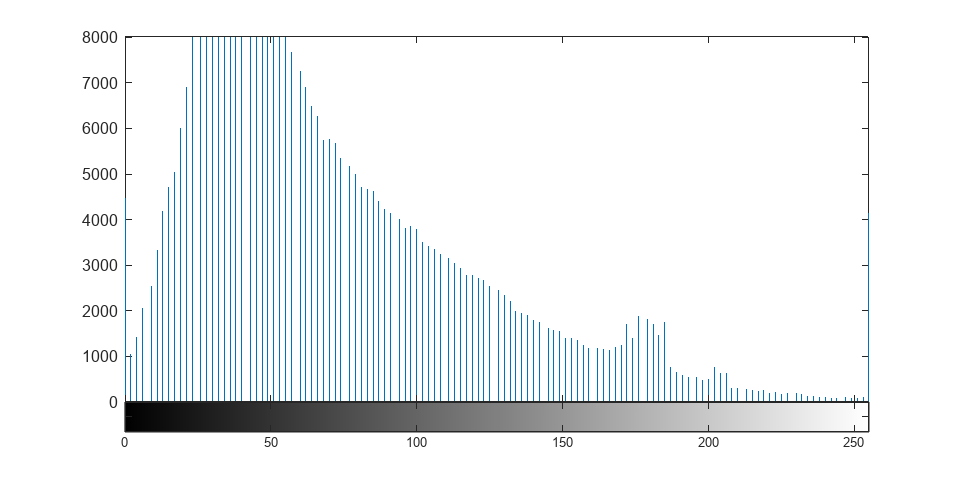

adjy1=imadjust(gy1);
imhist(adjy1)

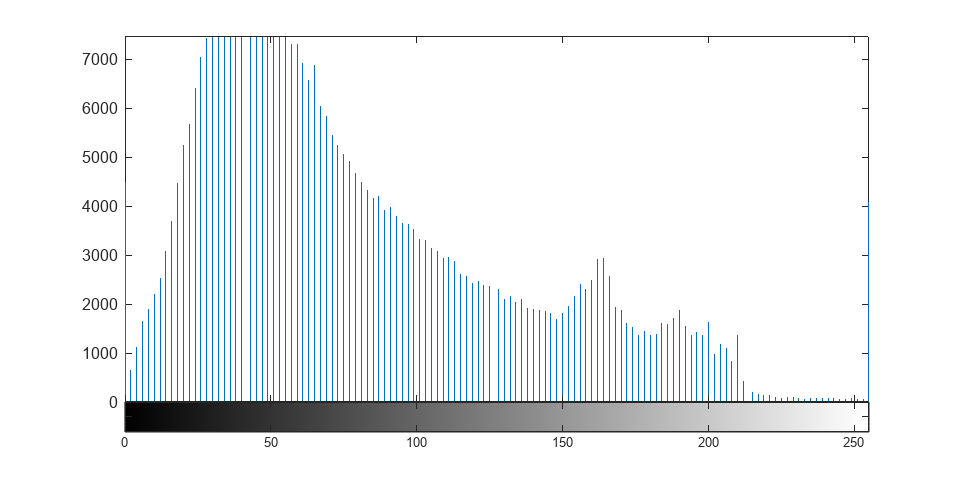

adjy2=imadjust(gy2);
imhist(adjy2)

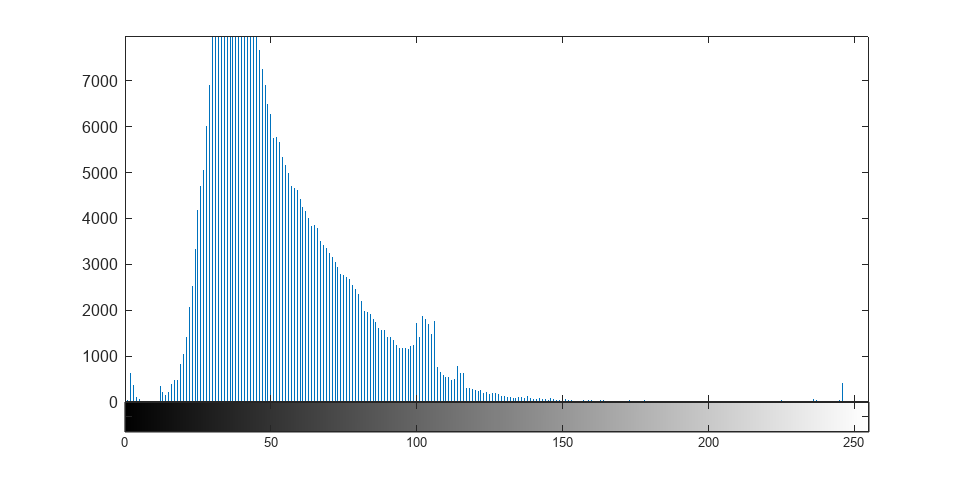

imhist(gy1)

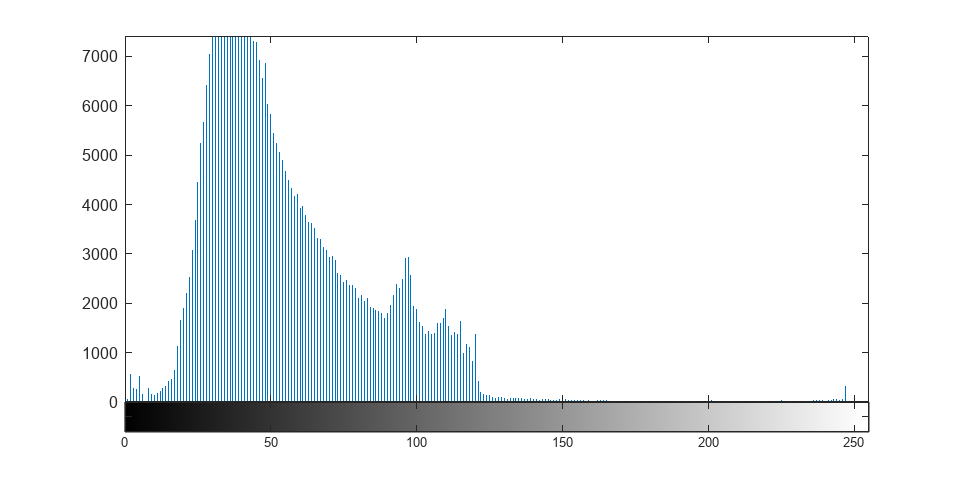

imhist(gy2)

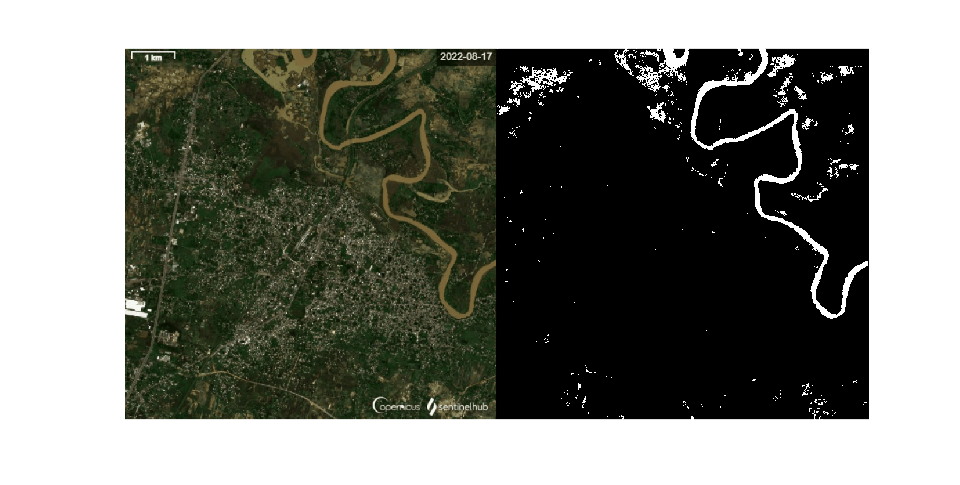


bw1=createMask(year1);
imshowpair(year1,bw1,"montage")

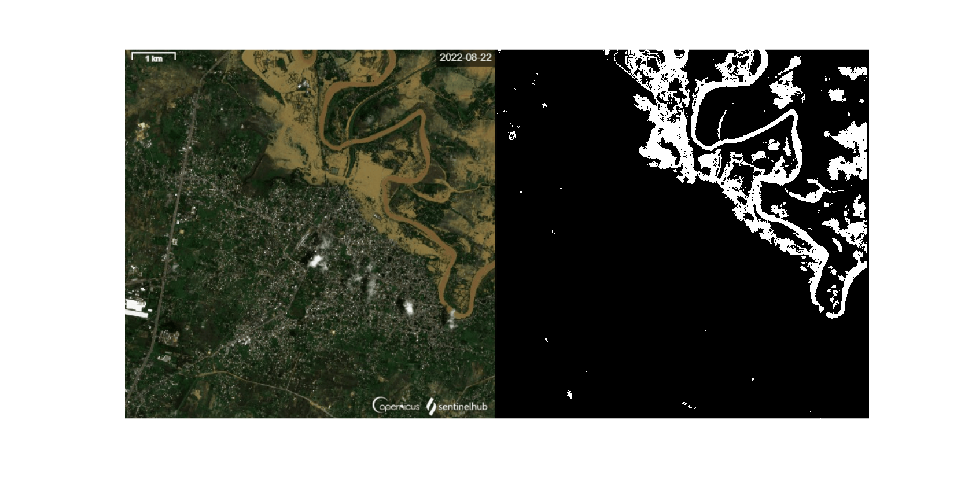


bw2=createMask(year2);
imshowpair(year2,bw2,"montage")


props1=regionprops("table",bw1,"Area")

props1 = 481×1 table
    Area
    ____

      2 
     12 
      4 
      2 
      1 
      1 
    152 
      3 
      2 
      1 
      4 
      5 
      1 
      2 
      5 
      5 


areaPixels1=sum(props1.Area)

areaPixels1 = 19398


props2=regionprops("table",bw2,"Area")

props2 = 216×1 table
    Area
    ____

      1 
     16 
     10 
      4 
      2 
      1 
    112 
      3 
      8 
      3 
      4 
     13 
      9 
     11 
      3 
      1 


areaPixels2=sum(props2.Area)

areaPixels2 = 45919


totArea=408958

totArea = 408958

percen1=(areaPixels1/totArea)*100  

percen1 = 4.7433

percen2=(areaPixels2/totArea)*100

percen2 = 11.2283

percen=percen2-percen1

percen = 6.4850